# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.17 有没有大佬知道这种图是用什么软件做的啊？

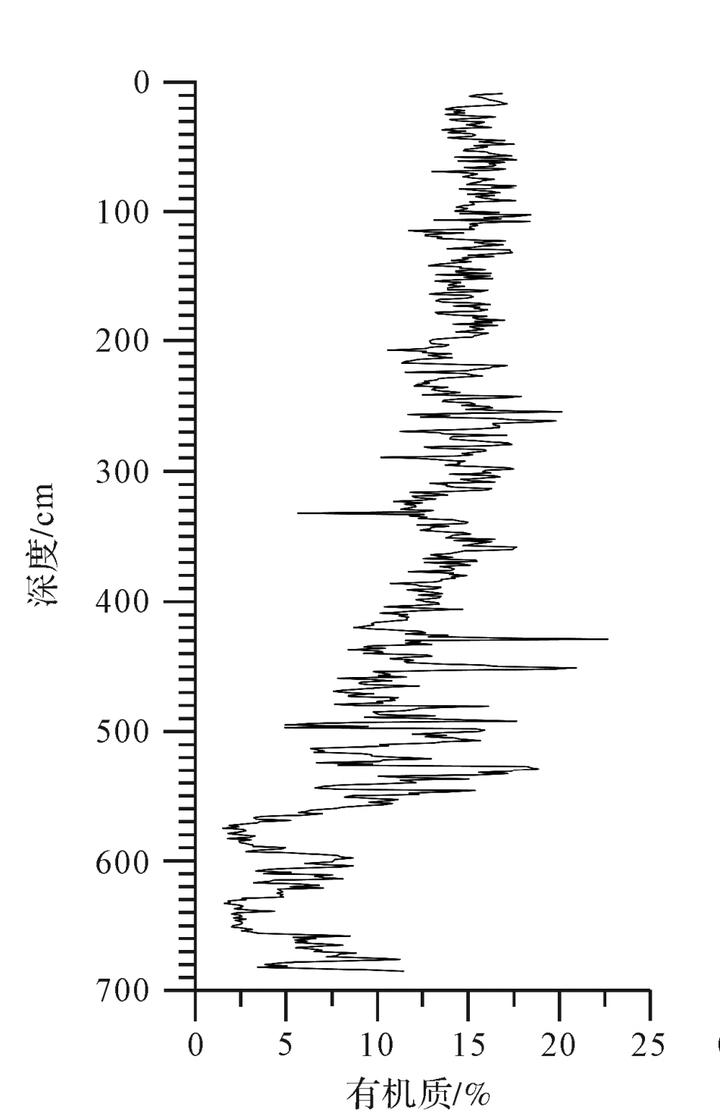

原问题：[https://www.zhihu.com/question/648265957/answer/3429544325](https://www.zhihu.com/question/648265957/answer/3429544325)

clear;clc;
% 随机整一些数据
y = 0:700;
y = y';
x = sin(y) + randn(length(y), 1);
% 先把宽高比例整一下
figure('Position', [0, 0, 600, 1200]);
% 最简单的绘图
plot(x, y, 'k', 'LineWidth', 1.5);
% 把边框干掉
box off
% y 轴给它倒置过来
axis ij
% 刻度线朝外
set(gca, 'TickDir', 'out');
% 小刻度整出来
set(gca, 'XMinorTick', 'on');
set(gca, 'YMinorTick', 'on');
xlim([-6, 4]);
ax = gca;
xticks(-6:4);
% 小刻度数量
ax.XAxis.MinorTickValues = linspace(-6, 4, 21);
% 线加粗
ax.LineWidth = 1.5;
% 轴标题
xlabel('有机质/%');
ylabel('深度/cm');